### part 1

global SAMPLEPERSEC ALPHA MAXFREQ;
SAMPLEPERSEC = 100;
MAXFREQ = 50;
ALPHA = 1;
characters = ['a':'z', ' ', '.', ',', '!', '"', ';'];

Mapset = cell(32,2);

for i = 1:length(characters)
    Mapset{i,1} = characters(i);
    Mapset{i,2} = dec2bin(i-1,5); 
end
Mapset

Mapset = 32×2 cell array
    {'a'}    {'00000'}
    {'b'}    {'00001'}
    {'c'}    {'00010'}
    {'d'}    {'00011'}
    {'e'}    {'00100'}
    {'f'}    {'00101'}
    {'g'}    {'00110'}
    {'h'}    {'00111'}
    {'i'}    {'01000'}
    {'j'}    {'01001'}
    {'k'}    {'01010'}
    {'l'}    {'01011'}
    {'m'}    {'01100'}
    {'n'}    {'01101'}
    {'o'}    {'01110'}
    {'p'}    {'01111'}
    {'q'}    {'10000'}
    {'r'}    {'10001'}
    {'s'}    {'10010'}
    {'t'}    {'10011'}
    {'u'}    {'10100'}
    {'v'}    {'10101'}
    {'w'}    {'10110'}
    {'x'}    {'10111'}
    {'y'}    {'11000'}
    {'z'}    {'11001'}
    {' '}    {'11010'}
    {'.'}    {'11011'}
    {','}    {'11100'}
    {'!'}    {'11101'}


- `SAMPLEPERSEC` تعداد نمونه‌ها در هر ثانیه را تنظیم می‌کند.

- `characters` شامل کاراکترهای قابل کدگذاری است.

- `Mapset` شامل کاراکترها و معادل دودویی ۵ بیتی آن‌ها است.

### part 2

در این بخش، روند کدگذاری پیام به صورت زیر انجام می‌شود:

- ابتدا یک جدول `Mapset` ایجاد می‌شود که هر کاراکتر از پیام ورودی (مثلاً حروف الفبا، فواصل و علائم نگارشی) به کد دودویی معادل خود نگاشت می‌شود. این کار برای تبدیل پیام به یک رشته دودویی انجام می‌شود.

- سپس، پیام ورودی به رشته‌ای از کدهای دودویی تبدیل می‌شود. این فرآیند با استفاده از `Mapset` انجام می‌شود تا هر کاراکتر از پیام به معادل دودویی خود تبدیل شود.

- پس از کدگذاری، پیام به بخش‌های کوچکتر تقسیم می‌شود. این تقسیم‌بندی بر اساس یک پارامتر به نام `transmission_speed` انجام می‌شود که طول هر بخش را مشخص می‌کند. این بخش‌ها برای پردازش و ارسال راحت‌تر آماده می‌شوند.

- سپس، هر بخش دودویی به یک سیگنال سینوسی تبدیل می‌شود. برای هر بخش دودویی، یک سیگنال سینوسی خاص تولید می‌شود که نماینده آن بخش از پیام است.

- در نهایت، تمامی سیگنال‌ها که هرکدام نمایانگر یک بخش از پیام هستند، به یک سیگنال پیوسته ترکیب می‌شوند. این سیگنال پیوسته در نهایت به عنوان خروجی برای ارسال پیام به سیستم گیرنده استفاده می‌شود.

در کل، روند کدگذاری پیام به این صورت است که ابتدا پیام به کد دودویی تبدیل می‌شود، سپس به بخش‌های کوچکتر تقسیم و در نهایت به سیگنال‌های سینوسی برای ارسال تبدیل می‌شود.

function encodedText = encodeTextWithMapset(Mapset, text)

tmp_encode = '10011001001001010011'

    % split code and char
    characters = [Mapset{:, 1}];
    codes = Mapset(:, 2);

    % map to char index
    [~, idx] = ismember(text, characters);
    
    % encode
    encodedText = strjoin(codes(idx), '');
end

tmp_encode = encodeTextWithMapset(Mapset, 'test')

- کاراکترهای ورودی را به رشته دودویی معادل آن‌ها بر اساس `Mapset` تبدیل می‌کند.

- از تابع `ismember` برای یافتن اندیس کاراکترها استفاده می‌شود.

- نتیجه نهایی رشته دودویی ترکیب‌شده است.

function semgments = segment_massage(transmission_speed, binary_message)

tmp_segments = 1×7 cell array
    {'100'}    {'110'}    {'010'}    {'010'}    {'010'}    {'100'}    {'11'}


    semgments = {};
    for i = 1:transmission_speed:strlength(binary_message)
        if i + transmission_speed - 1 <= strlength(binary_message)
            segment = binary_message(i:i+transmission_speed-1);
        else
            segment = binary_message(i:end);
        end
       semgments{end+1} = segment;
    end
end

tmp_segments = segment_massage(3, tmp_encode)

- پیام دودویی را به بخش‌هایی با طول `transmission_speed` تقسیم می‌کند.

- اگر طول پیام کامل نباشد، بخش آخر کوتاه‌تر خواهد بود.

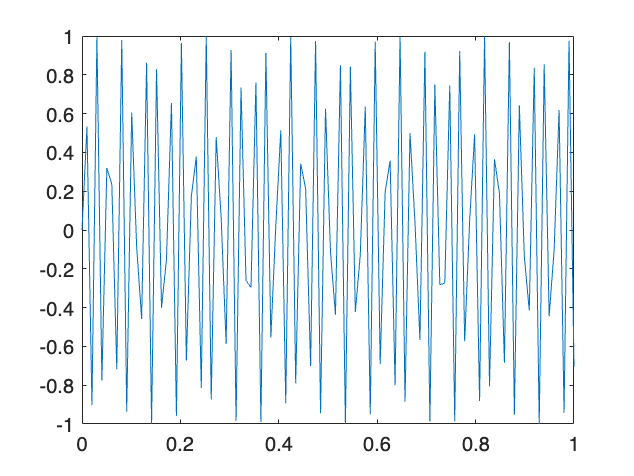

function signal = binaryToSignal(segment, t, transmission_speed)
    global ALPHA;

    global MAXFREQ;
    max_value = 2^transmission_speed - 1;
    signal = zeros(size(t));

    for i = 0:max_value
        if strcmp(dec2bin(i, transmission_speed), segment)
            f = (2*i + 1)/(2^(transmission_speed+1)) * MAXFREQ;
            signal = ALPHA * sin(2 * pi * f * t);
        end
    end
end

tmp_x = linspace(0, 1, SAMPLEPERSEC);
plot(tmp_x, binaryToSignal(tmp_segments(2), tmp_x, 3));

- بخش دودویی ورودی را به سیگنال سینوسی تبدیل می‌کند.

- مقدار سیگنال بر اساس مقدار دودویی نسبت به حداکثر مقدار ممکن تنظیم می‌شود.

- از تابع `strcmp` برای مقایسه رشته‌ها استفاده می‌کند.

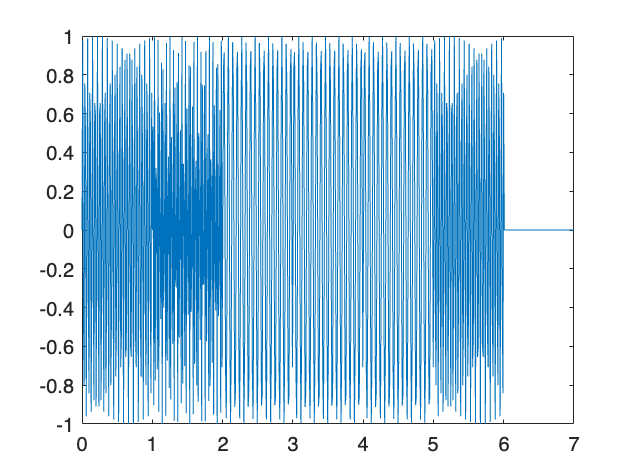

function encoded_message = convert_to_signal(semgments, transmission_speed)
    global SAMPLEPERSEC;
    t = linspace(0, 1, SAMPLEPERSEC);


    encoded_message = zeros(1, length(t) * length(semgments));

    for i = 1:length(semgments)
       segment = semgments{i};
       signal = binaryToSignal(segment, t, transmission_speed);
        start_idx = (i-1)*length(t) + 1;
        end_idx = i*length(t);
        encoded_message(start_idx:end_idx) = signal;
    end
end

tmp_signal = convert_to_signal(tmp_segments, 3);
tmp_x = linspace(0, length(tmp_signal)/SAMPLEPERSEC, length(tmp_signal)); 
plot(tmp_x ,tmp_signal);

- تمام بخش‌های دودویی را به سیگنال‌های سینوسی تبدیل و در یک سیگنال پیوسته قرار می‌دهد.

- از `SAMPLEPERSEC` برای تنظیم تعداد نمونه‌ها استفاده می‌کند.

- سیگنال نهایی از ترکیب تمامی بخش‌ها ساخته می‌شود.

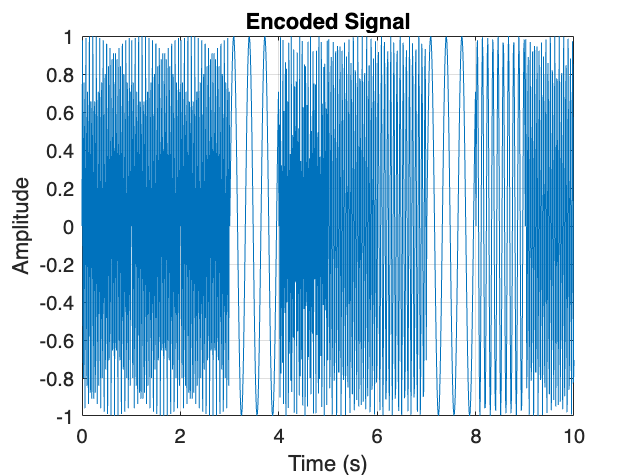

function encoded_message = coding_freq(message, transmission_speed, Mapset)
    message = char(message);
    binary_message = encodeTextWithMapset(Mapset,message);

    semgments = segment_massage(transmission_speed, binary_message);


    encoded_message = convert_to_signal(semgments, transmission_speed);

end

- پیام ورودی را به کد دودویی تبدیل می‌کند.

- پیام دودویی را به بخش‌های کوچک‌تر تقسیم می‌کند.

- سیگنال پیوسته را با استفاده از بخش‌های دودویی تولید می‌کند.

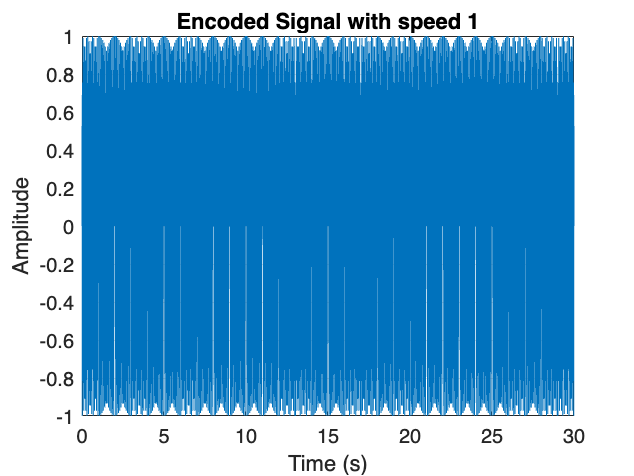

message = 'signal';
speed = 3;
encoded_message = coding_freq(message, speed, Mapset);

t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
plot(t, encoded_message);
xlabel('Time (s)');
ylabel('Amplitude');
title('Encoded Signal');

grid on;

- سیگنال کدگذاری‌شده رسم می‌شود.

- برچسب‌های زمان و دامنه تنظیم شده‌اند.

- `grid on` برای نمایش بهتر نمودار فعال می‌شود.

### part 3

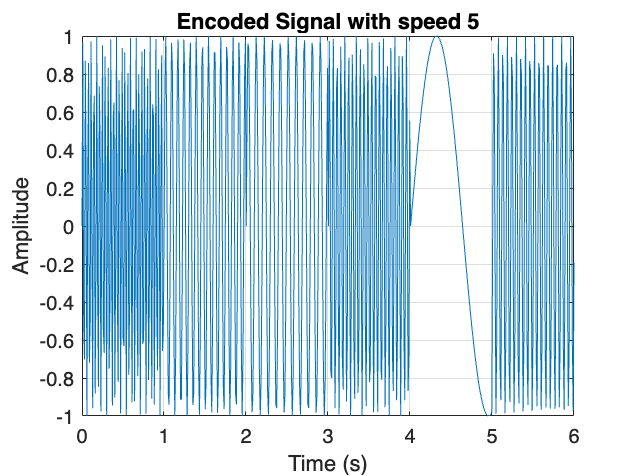

message = 'signal';
speed = 1;
encoded_message = coding_freq(message, speed, Mapset);

t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
plot(t, encoded_message);
xlabel('Time (s)');
ylabel('Amplitude');
title('Encoded Signal with speed 1');
grid on;

message = 'signal';
speed = 5;
encoded_message = coding_freq(message, speed, Mapset);
 

Decoded string with speed 5: signal


t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
plot(t, encoded_message);
xlabel('Time (s)');
ylabel('Amplitude');

Decoded string with speed 4: signal


title('Encoded Signal with speed 5');
grid on;

### part 4

function bits_Mapset = createBitsMapset(bit_rate)
    % Initialize a cell array with 2^bit_rate elements to store binary strings

Decoded string with speed 3: signal


    bits_Mapset = cell(2^bit_rate, 1);
    
    % Loop through numbers from 0 to 2^bit_rate - 1
    for i = 1:2^bit_rate

Decoded string with speed 2: signal


        % Convert the decimal number (i-1) to a binary string of length bit_rate
        % and store it in the corresponding cell array position
        bits_Mapset{i} = dec2bin(i - 1, bit_rate);
    end

Decoded string with speed 1: signal


end


function freqs = generateTargetFrequencies(bit_rate, fs)
    step = fs / (2^bit_rate); % Calculate the frequency step size based on bit rate and sampling frequency
    freqs = step/2:step:fs - step/2; % Generate target frequencies centered within each step
end

function bits = extractBitsFromResult(signal, bit_rate, fs, freqs)
    bits = '';
    N = fs; % Segment length for 1-second intervals

    for i = 1:N:length(signal)
        segment = signal(i:i+N-1);
        Y = fft(segment);
        Y_shifted = fftshift(Y);
        f_axis = (-N/2:N/2-1)*(fs/N);
        
        % Find the peak frequency
        [~, idx] = max(abs(Y_shifted));
        detected_freq = abs(f_axis(idx));
        
        % Find the closest target frequency
        [~, bit_idx] = min(abs(freqs - detected_freq));
        bits = [bits, dec2bin(bit_idx - 1, bit_rate)];
    end
end


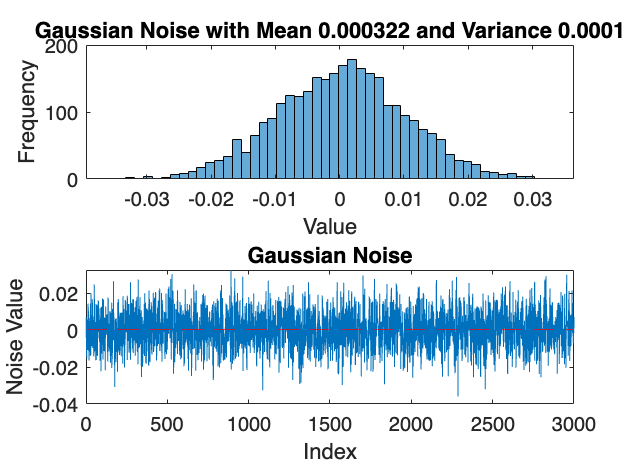

function output_string = decodeBits(bits, Mapset)

noise_mean = 2.4037e-04

noise_variance = 9.9924e-05

Decoded string with speed 1: signal


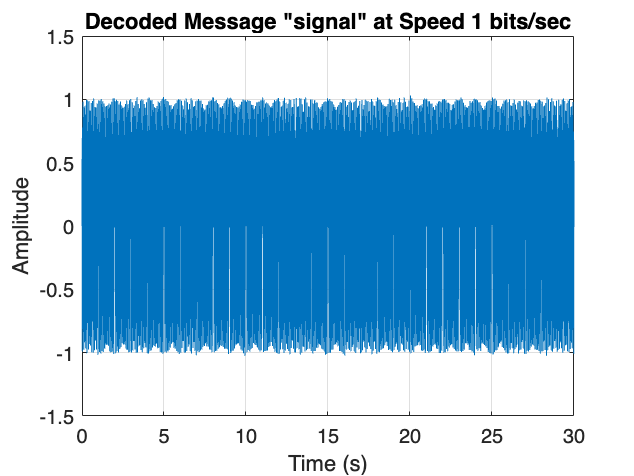

noise_mean = -4.5565e-04

noise_variance = 9.9888e-05

Decoded string with speed 5: signal


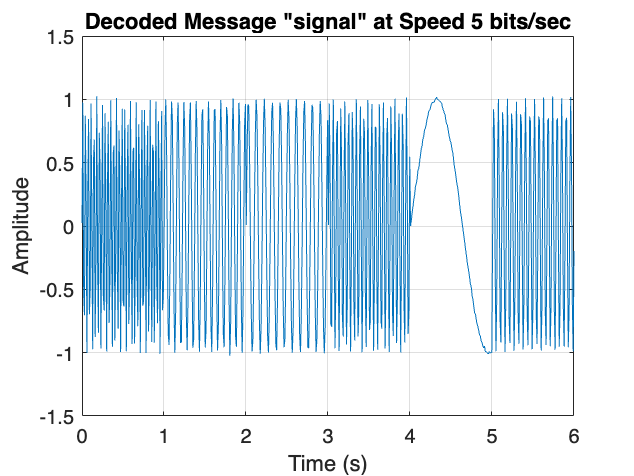

    bit_rate = 5; % Define the bit rate for decoding
    n_chars = length(bits) / bit_rate; % Calculate the number of characters to decode

    output_string = ''; % Initialize the output string

    % Loop through each character segment in the input bits
    for i = 1:n_chars
        % Extract the current bit chunk corresponding to one character
        bit_chunk = bits((i-1)*bit_rate + 1:i*bit_rate);
        
        % Search for the corresponding character in the Mapset
        for j = 1:length(Mapset)
            if strcmp(bit_chunk, Mapset{j, 2}) % Compare bit chunk with Mapset entry
                output_string = [output_string, Mapset{j, 1}]; % Append the matching character to output
                break; % Stop searching once a match is found
            end
        end
    end
end

function output_string = decoding_freq(signal, bit_rate, Mapset)
    fs = 100; % 100 sample per second
    freqs = generateTargetFrequencies(bit_rate, 50);
    bits_Mapset = createBitsMapset(bit_rate);
    

-----------------------------------------


    % Extract bits and decode
    bits = extractBitsFromResult(signal, bit_rate, fs, freqs);
    output_string = decodeBits(bits, Mapset);
    disp(['Decoded string with speed ', num2str(bit_rate), ': ', output_string]);

end

message = 'signal';
speed = 5;
encoded_message = coding_freq(message, speed, Mapset);
decoding_freq(encoded_message, speed, Mapset);

speed = 4;
encoded_message = coding_freq(message, speed, Mapset);
decoding_freq(encoded_message, speed, Mapset);

speed = 3;

Decoded string with speed 1: abcdgfghijklmno


Variance: 1, Match: 0


Decoded string with speed 1: abcdefghijklmno


Variance: 1.1, Match: 1


Decoded string with speed 1: abcdefghijklmno


Variance: 1.2, Match: 1


Decoded string with speed 1: abcdefghijklmno


Variance: 1.3, Match: 1


Decoded string with speed 1: abcdefghijklmnp


Variance: 1.4, Match: 0


Decoded string with speed 1: abcdefghizklmno


Variance: 1.5, Match: 0


Decoded string with speed 1: abcdefgxilklmno


Variance: 1.6, Match: 0


Decoded string with speed 1: adcdefghijklonp


Variance: 1.7, Match: 0


Decoded string with speed 1: abcdefghijklmno


Variance: 1.8, Match: 1


Decoded string with speed 5: abcdefghijklmno


Variance: 1, Match: 1


Decoded string with speed 5: abcdefghijklmoo


Variance: 1.1, Match: 0


Decoded string with speed 5: abcdefghijklmno


Variance: 1.2, Match: 1


Decoded string with speed 5: abcdefghijklmno


Variance: 1.3, Match: 1


Decoded string with speed 5: abcdefghijklmno


Variance: 1.4, Match: 1


Decoded string with speed 5: abcdefghijmlmno


Variance: 1.5, Match: 0


Decoded string with speed 5: abcdefghijklmno


Variance: 1.6, Match: 1


Decoded string with speed 5: abcdefghijklmoo


Variance: 1.7, Match: 0


Decoded string with speed 5: abcdefghtjklmno


Variance: 1.8, Match: 0


encoded_message = coding_freq(message, speed, Mapset);
decoding_freq(encoded_message, speed, Mapset);

speed = 2;
encoded_message = coding_freq(message, speed, Mapset);
decoding_freq(encoded_message, speed, Mapset);

speed = 1;
encoded_message = coding_freq(message, speed, Mapset);
decoding_freq(encoded_message, speed, Mapset);

### part 5

**ولید نویز گوسی با میانگین صفر و واریانس یک**:

- با استفاده از دستور `randn(1, 3000)`, نویز گوسی با میانگین صفر و واریانس یک تولید می‌شود.

- بررسی می کنیم نویز خواص گفته شده را داشته باشد.


variance = 0.0001;
% Generate Gaussian noise with mean 0 and variance 0.0001
noise = sqrt(variance) * randn(1, 3000); 

% Calculate the mean and variance of the generated noise
noise_mean = mean(noise);
noise_variance = var(noise);

% Create figure with two subplots
figure;

% First subplot: Histogram of the noise
subplot(2, 1, 1);
histogram(noise, 50);
title(sprintf('Gaussian Noise with Mean %.6f and Variance %.4f', noise_mean, noise_variance));
xlabel('Value');
ylabel('Frequency');

% Second subplot: Plot of the noise
subplot(2, 1, 2);
plot(noise);
title('Gaussian Noise');
xlabel('Index');
ylabel('Noise Value');
hold on;
yline(noise_mean, 'r--');  % Add red dashed line for the mean


sigma = sqrt(0.0001);
message = 'signal';
speeds = [1, 5];

for i = 1:length(speeds)
    speed = speeds(i);
    encoded_message = coding_freq(message, speed, Mapset);
    
    noise = sigma * randn(1, length(encoded_message));
    noise_mean = mean(noise)
    noise_variance = var(noise)

    noisy_message = encoded_message + noise;
    
    result = decoding_freq(noisy_message,speed, Mapset);
    figure;
    t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
    plot(t, noisy_message);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Decoded Message "%s" at Speed %d bits/sec',result, speed));
    grid on;
end

### part 6

message = 'abcdefghijklmno';
speeds = [1, 5];
noise_variances =  (1:0.1:1.8);

disp(['-----------------------------------------']);
for i = 1:length(speeds)
    speed = speeds(i);
    encoded_message = coding_freq(message, speed, Mapset);
    
    for j = 1:length(noise_variances)
        noise_power = noise_variances(j);
        sigma = sqrt(noise_power);
        noise = sigma * randn(size(encoded_message));
        noisy_signal = encoded_message + noise;

        result = decoding_freq(noisy_signal,speed, Mapset);
        disp(['Variance: ', num2str(noise_power), ', Match: ', num2str(all(result == message))]);
    end
end

### part 7

برای سرعت ۵ بیت بر ثانیه، بیشترین نویز که میتونست تحمل کنه، ۱.۷ بود، البته توی تست های مختلف جوابای مختلف گرفتم ولی این طبق تست آخرم بود.

برای سرعت یک بیت بر ثانیه، طبق تست آخرم، تا نویز ۱.۲ رو تونست تحمل کنه.

به طرز عجیبی، سرعت ۵ بیت بر ثانیه بهتر از سرعت ۱ بیت بر ثانیه عمل میکنه در بیشتر تست هایی که گرفتم. یعنی آستانه تحمل نویزش بیشتر بود. البته الان دوباره گرفتم برای سرعت ۵ بیت بر ثانیه شد همون ۱ ولی برای ۱ بیت بر ثانیه شد ۱.۲

ولی منطقا باید اونی که سرعت بیت بر ثانیه کمتری داره چون فاصله بین فرکانس هاش زیاده باید بتونه نویز بیشتری رو تحمل کنه، پس منطقا باید ۱ بیت بر ثانیه توانایی تحمل نویز بیشتری داشته باشه نسبت به ۵ بیت بر ثانیه

### part 8

همونطوری که به این سوال پاسخ دادیم، اگه دامنه سیگنال تولیدی رو قبل از اینکه نویز بهش وارد بشه، چند برابر کنیم، نویز کمتر میتونه روش تاثیر بذاره، چون فاصله بین فرکانس ها زیادتر میشه و بیشتر میتونه نویز رو تحمل کنه. مثلا اگه دامنه رو ۵ برابر کنییم، میتونیم حداکثر تا ۵ برابر بیشتر نویز رو تحمل کنیم.

### part 9

در صورتی که نویز ما خیلی کم باشد، در صورتی که نرخ نمونه برداری رو مثلا از ۱۰۰ ببریم به ۲۰۰ یا بیشتر، باعث میشه که بتونیم سرعت بیت بر ثانیه رو تا حد کمی افزایش بدیم اما از اون سمت، به همان میزان، کمتر نسبت به نویز مقاوم تر خواهد بود. مثلا اگه ما نرخ نمونه برداری رو دو برابر کنیم، شهودی میشه گفت که آستانه مقاومتش نسبت به نویز نصف خواهد شد. پس کلا اینکار باعث افزایش مقاومت نسبت به نویز نمیشه، بلکه حتی میتونه باعث کاهشش بشه.